# Otimização dos ganhos dos observadores

clear; close all; clc

reset(0)

Para facilitar, criou-se funções auxiliares para algumas partes do código. Vamos adicioná-las ao path.

addpath(genpath('./functions'))

## Parâmetros da simulação

dt = 2.5E-3;  % Para que a gente consiga visualizar bem e seja rapido
f_sr = 1/dt;
T = 32;  % Deve ser par
CI = [0; 0; 0; 0];
[b_filter, a_filter] = butter(2, 75/(f_sr*pi), 'low');   % wc = 25 + wn2 (padrao)

## Geração do sinal de chirp e ruido

% TODO: Colocar aqui tambem a parte de gerar o sinal de chirp e ruido
% e colocar na simulacao o caminho certo tb... Outra opçao eh criar um 
% outro scrip para fazer isso em ambas. Importante fazer isso pois
% garantimos que o sinal estara amostrado corretamente para a filtragem

## Parâmetros da suspensão da quanser e matrizes do sistema

mv = 2.45;  % [mv] = kg --> Massa de 1/4 do veiculo
% mv = 1.45;  % [mv] = kg --> Massa de 1/4 do veiculo
ks = 900;   % [ks] = N/m --> Constante elastica da suspensao
bs = 7.5;   % [bs] = Ns/m --> Coeficiente de amortecimento da suspensao
mr = 1;     % [mr] = kg --> Massa do eixo-roda
kp = 1250;  % [kp] = N/m --> Constante elastica do pneu
bp = 5;     % [bp] = Ns/m --> Coeficiente de amortecimento do pneu

[A, B1, B2, C, D] = define_system(mv, ks, bs, mr, kp, bp);
C_obs1 = C(1,:);
D_obs1 = D(1);
C_obs2 = C(2,:);
D_obs2 = D(2);

p = eig(A);

## Situações de dano

#### Caso 1: Sem dano

[A_c0, B1_c0, B2_c0, C_c0, D_c0] = define_system(mv, ks, bs, mr, kp, bp);

#### Caso 1: Perda do amortecimento da suspensão de 50%

bs_ = 0.5*bs;
[A_c1, B1_c1, B2_c1, C_c1, D_c1] = define_system(mv, ks, bs_, mr, kp, bp);

#### Caso 2: Perda da rigidez da mola da suspensão de 50%

ks_ = 0.5*ks;
[A_c2, B1_c2, B2_c2, C_c2, D_c2] = define_system(mv, ks_, bs, mr, kp, bp);

#### Caso 3: Perda de amortecimento da suspensão e da rigidez da mola de 50%

bs_ = 0.5*bs; ks_ = 0.5*ks;
[A_c3, B1_c3, B2_c3, C_c3, D_c3] = define_system(mv, ks_, bs_, mr, kp, bp);

#### Selecionando situação de dano

sim_case = '1';
A_sim_case = eval(sprintf('A_c%s', sim_case));
B1_sim_case = eval(sprintf('B1_c%s', sim_case));
B2_sim_case = eval(sprintf('B2_c%s', sim_case));
C_sim_case = eval(sprintf('C_c%s', sim_case));
D_sim_case = eval(sprintf('D_c%s', sim_case));

## Observador único com entrada $\omega(t)$

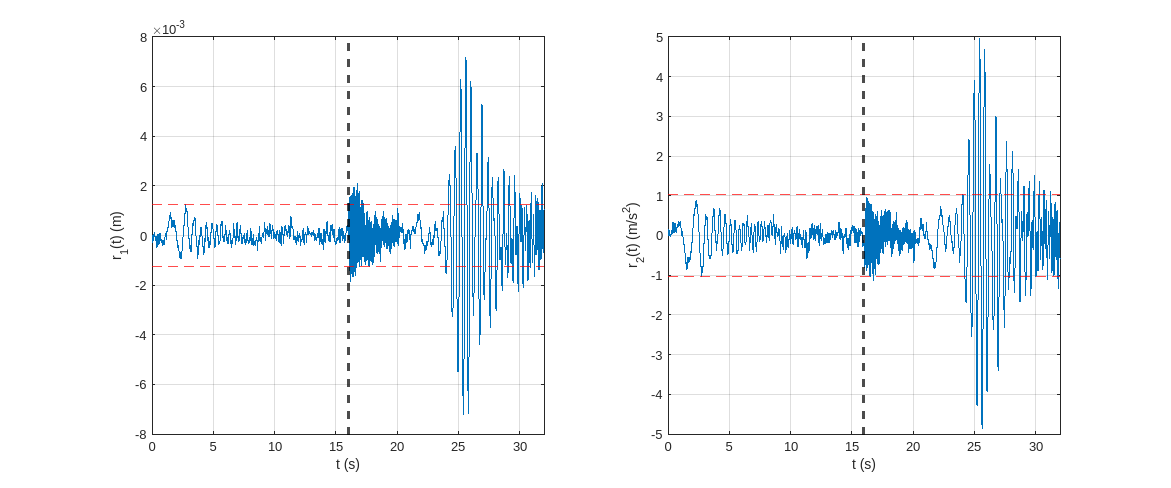

Velocidades: 7.00 & 0.00 
Limiares: 1.26e-03 & 1.04e+00

r_mul =7;
i_mul =0;
 

p_real = r_mul*real(p);
p_imag = i_mul*imag(p);

p_obsu_w = p_real + p_imag*1j;
if i_mul == 0
    p_obsu_w(2) = 1.25*p_obsu_w(1);
    p_obsu_w(4) = 1.25*p_obsu_w(3);
end

Ko = place(A', C', p_obsu_w)';

run_simu('./simulations', 'luenberger_obsu_w_design', r_mul, i_mul, b_filter, a_filter);

#### Melhor encontrado: $a = 7$ e $b = 0$.

## Observador 1 com entrada $\omega(t)$

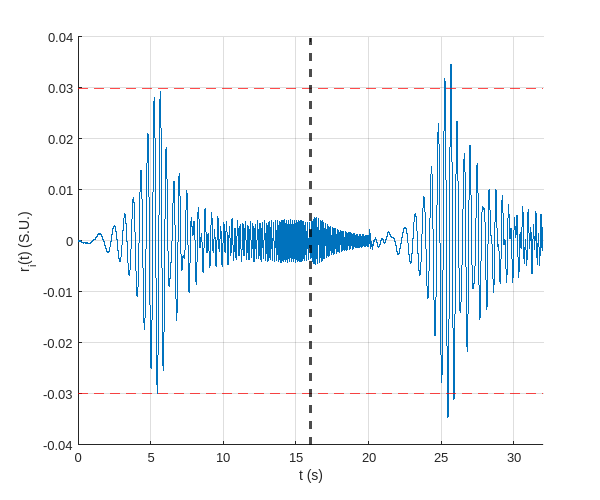

Velocidades: 4.00 & 4.00 
Limiar: 3.00e-02

r_mul =4;
i_mul =4;
 

p_real = r_mul*real(p);
p_imag = i_mul*imag(p);

p_obs1_w = p_real + p_imag*1j;
if i_mul == 0
    p_obs1_w(2) = 1.25*p_obs1_w(1);
    p_obs1_w(4) = 1.25*p_obs1_w(3);
end

Ko = place(A', C_obs1', p_obs1_w)';

run_simi('./simulations', 'luenberger_obs1_w_design', r_mul, i_mul, b_filter, a_filter);

#### Melhor encontrado: $a = 4$ e $b = 4$.

## Observador 2 com entrada $\omega(t)$

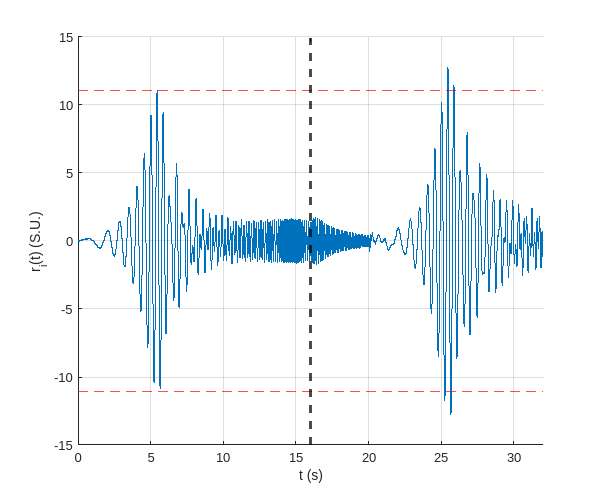

Velocidades: 4.00 & 4.00 
Limiar: 1.11e+01

r_mul =4;
i_mul =4;
 

p_real = r_mul*real(p);
p_imag = i_mul*imag(p);

p_obs2_w = p_real + p_imag*1j;
if i_mul == 0
    p_obs2_w(2) = 1.25*p_obs2_w(1);
    p_obs2_w(4) = 1.25*p_obs2_w(3);
end

Ko = place(A', C_obs2', p_obs2_w)';

run_simi('./simulations', 'luenberger_obs2_w_design', r_mul, i_mul, b_filter, a_filter);

#### Melhor encontrado: $a = 4$ e $b = 4$.

## Observador único com entrada $u(t)$

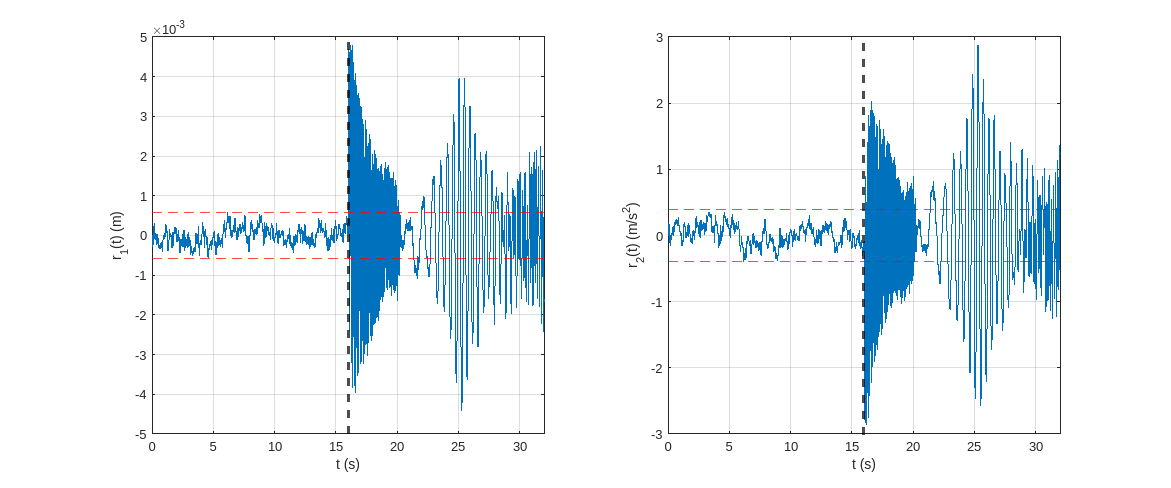

Velocidades: 7.00 & 0.00 
Limiares: 5.91e-04 & 3.90e-01

r_mul =7;
i_mul =0;
 

p_real = r_mul*real(p);
p_imag = i_mul*imag(p);

p_obsu_u = p_real + p_imag*1j;
if i_mul == 0
    p_obsu_u(2) = 1.25*p_obsu_u(1);
    p_obsu_u(4) = 1.25*p_obsu_u(3);
end

Ko = place(A', C', p_obsu_u)';

run_simu('./simulations', 'luenberger_obsu_u_design', r_mul, i_mul, b_filter, a_filter);

#### Melhor encontrado: $a = 7$ e $b = 0$.

## Observador 1 com entrada $u(t)$

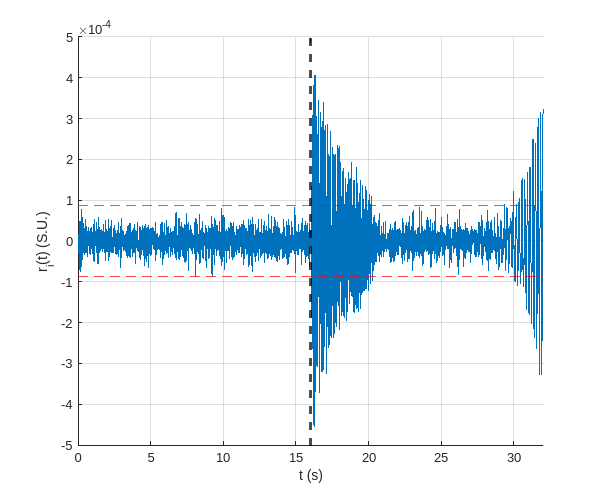

Velocidades: 5.50 & 2.50 
Limiar: 8.68e-05

r_mul =5.5;
i_mul =2.5;
 

p_real = r_mul*real(p);
p_imag = i_mul*imag(p);

p_obs1_u = p_real + p_imag*1j;
if i_mul == 0
    p_obs1_u(2) = 1.25*p_obs1_u(1);
    p_obs1_u(4) = 1.25*p_obs1_u(3);
end

Ko = place(A', C_obs1', p_obs1_u)';

run_simi('./simulations', 'luenberger_obs1_u_design', r_mul, i_mul, b_filter, a_filter);

#### Melhor encontrado: $a = 5.5$ e $b = 2.5$.

## Observador 2 com entrada $u(t)$

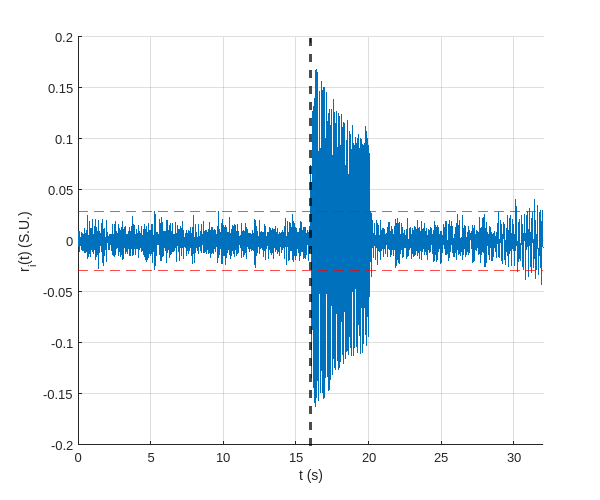

Velocidades: 5.50 & 2.50 
Limiar: 2.94e-02

r_mul =5.5;
i_mul =2.5;
 

p_real = r_mul*real(p);
p_imag = i_mul*imag(p);

p_obs2_u = p_real + p_imag*1j;
if i_mul == 0
    p_obs2_u(2) = 1.25*p_obs2_u(1);
    p_obs2_u(4) = 1.25*p_obs2_u(3);
end

Ko = place(A', C_obs2', p_obs2_u)';

run_simi('./simulations', 'luenberger_obs2_u_design', r_mul, i_mul, b_filter, a_filter);

#### Melhor encontrado: $a = 5.5$ e $b = 2.5$.

## Filtro de Kalman - Determinção dos limiares para todos os caso

#### Leitura dos dados

load('../data/chirp_u_data.mat')
load('../data/chirp_w_data.mat')
load('../data/measurement_noise_u_data.mat')
load('../data/measurement_noise_w_data.mat')
load('../data/process_noise_u_data.mat')

w = squeeze(wt.Data);
W = cov(w);
v_y1_w = squeeze(vt_w.Data(1,1,:));
v_y2_w = squeeze(vt_w.Data(2,1,:));

u = squeeze(ut.Data);
v_y1_u = squeeze(vt_u.Data(1,1,:));
v_y2_u = squeeze(vt_u.Data(2,1,:));

v_var_y1_w = cov(v_y1_w);
v_var_y2_w = cov(v_y2_w);
V_w = cov(v_y1_w, v_y2_w);

v_var_y1_u = cov(v_y1_u);
v_var_y2_u = cov(v_y2_u);
V_u = cov(v_y1_u, v_y2_u); 

#### Projeto dos filtros

% Gerando ruido de processo
v_pu = squeeze(vt_pu.Data);
U = cov(v_pu);
%%%% Entrada w
%%%%% Banco de Observadores
[Ko1_kalman_w, ~, ~] = lqe(A, B1, C_obs1, W, v_var_y1_w);  % Tem que ser v_var_y1 porque eh da saida 1 apenas
[Ko2_kalman_w, ~, ~] = lqe(A, B1, C_obs2, W, v_var_y2_w);  % Idem
%%%%% Observador unico
[Kou_kalman_w, ~, ~] = lqe(A, B1, C, W, V_w);  % Agora eh V porque tem a matriz de covariancia...
%%%% Entrada u
% %%%%% Banco de Observadores
[Ko1_kalman_u, ~, ~] = lqe(A, B2, C_obs1, U, v_var_y1_u);  % Tem que ser v_var_y1 porque eh da saida 1 apenas
[Ko2_kalman_u, ~, ~] = lqe(A, B2, C_obs2, U, v_var_y2_u);  % Idem
% %%%%% Observador unico
[Kou_kalman_u, ~, ~] = lqe(A, B2, C, U, V_u);  % Agora eh V porque tem a matriz de covariancia...

### Entrada $\omega(t)$

[~, ~, y, ~, ~, ~, y_hat_obsu, y1_hat_obs1, y2_hat_obs2] = run_sim('./simulations', 'kalman_w_');

#### Observador único com entrada $\omega(t)$

r1_obs = filter(b_filter, a_filter, (y.y1 - y_hat_obsu.y1_hat));
r2_obs = filter(b_filter, a_filter, (y.y2 - y_hat_obsu.y2_hat));
fprintf('Limiar r1: %.2d\nLimiar r2: %.2d', max(abs(r1_obs(1:ceil(length(r1_obs)/2)))), max(abs(r2_obs(1:ceil(length(r2_obs)/2)))))

Limiar r1: 1.86e-02
Limiar r2: 6.09e+00

#### Observador 1 com entrada $\omega(t)$

r1_obs = filter(b_filter, a_filter, (y.y1 - y1_hat_obs1.y1_hat));
fprintf('Limiar r1: %.2d', max(abs(r1_obs(1:ceil(length(r1_obs)/2)))))

Limiar r1: 1.76e-02

#### Observador 2 com entrada $\omega(t)$

r2_obs = filter(b_filter, a_filter, (y.y2 - y2_hat_obs2.y2_hat));
fprintf('Limiar r2: %.2d', max(abs(r2_obs(1:ceil(length(r2_obs)/2)))))

Limiar r2: 5.92e+00

### Entrada $u(t)$

[~, ~, y, ~, ~, ~, y_hat_obsu, y1_hat_obs1, y2_hat_obs2] = run_sim('./simulations', 'kalman_u_');

#### Observador único com entrada $u(t)$

r1_obs = filter(b_filter, a_filter, (y.y1 - y_hat_obsu.y1_hat));
r2_obs = filter(b_filter, a_filter, (y.y2 - y_hat_obsu.y2_hat));
fprintf('Limiar r1: %.2d\nLimiar r2: %.2d', max(abs(r1_obs(1:ceil(length(r1_obs)/2)))), max(abs(r2_obs(1:ceil(length(r2_obs)/2)))))

Limiar r1: 5.71e-02
Limiar r2: 2.19e+01

#### Observador 1 com entrada $u(t)$

r1_obs = filter(b_filter, a_filter, (y.y1 - y1_hat_obs1.y1_hat));
fprintf('Limiar r1: %.2d', max(abs(r1_obs(1:ceil(length(r1_obs)/2)))))

Limiar r1: 6.27e-02

#### Observador 2 com entrada $u(t)$

r2_obs = filter(b_filter, a_filter, (y.y2 - y2_hat_obs2.y2_hat));
fprintf('Limiar r2: %.2d', max(abs(r2_obs(1:ceil(length(r2_obs)/2)))))

Limiar r2: 2.31e+01